# Transfer Learning Using Pretrained AlexNet Network

This live script uses transfer learning to train a deep network that can classify images of faces.

clc;
clear;
close all;

## Create a network by modifying AlexNet

Load/Access/Import the pretrained AlexNet model and save in a variable called deepnet

deepnet = alexnet; % The variable deepnet represents a deep convolutional network

See details of the architecture

% Extract the Layers property of deepnet into a variable called ly
ly = deepnet.Layers; % The variable ly is an array of network layers

For transfer learning, the input and output layers are the most relevant layers

Here we will modify two layers for transfer learning - fully connected layer and classification layer

% Extract the twenty-third layer which is the fully connected layer
% i.e., classify two faces, then set as 2
ly(23) = fullyConnectedLayer(2); % Returns a fully connected layer and specifies the OutputSize property

% Extract the twenty-fifth layer which is the classification/output layer
ly(25) = classificationLayer; % https://www.mathworks.com/help/deeplearning/ref/classificationlayer.html#d123e22943

## Get training images

Create a datastore named 'faceds' to store face images

% 'Faces' is the folder name
% 'IncludeSubfolders' option to look for images within subfolders of the given folder
faceds = imageDatastore('Faces','IncludeSubfolders',true,'LabelSource','foldernames'); % Manage a collection of image files

Extract the file names of the images

% fname = faceds.Files

Extract the Labels property of faceds

% facenames = faceds.Labels

Simple preprocessing

% An augmented image datastore can perform simple preprocessing on an entire collection of images
% faceauds = augmentedImageDatastore([227 227],faceds)

Split into training and testing sets

% Split images into two datastores, random select 70% to put in faceTrain
[faceTrain, faceTest] = splitEachLabel(faceds,0.7,'randomized');

## Set training algorithm options

Lower the learning rate for transfer learning

% Use the stochastic gradient descent with momentum for optimization
opts = trainingOptions('sgdm','InitialLearnRate',0.001);

## Perform training

% Train new network
% Insert data, layers, options to the trainNetwork function
facenet = trainNetwork(faceTrain,ly,opts);

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |       71.88% |       0.8282 |          0.0010 |
|      30 |          30 |       00:00:44 |      100.00% |   4.3589e-05 |          0.0010 |
|========================================================================================|
Training finished: Max epochs completed.


## Use the trained network to classify test images

testpreds = classify(facenet,faceTest);

## Evaluate the results

Calculate the accuracy

nnz(testpreds == faceTest.Labels)/numel(testpreds)

ans = 1

Visualize the confusion matrix

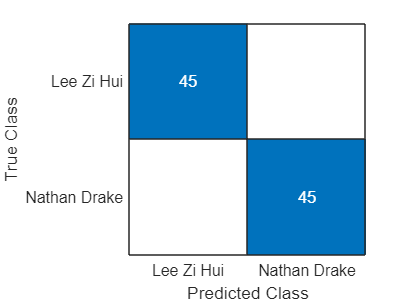

confusionchart(faceTest.Labels,testpreds);